% AAE 532 HW 6 Problem 1
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps6';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
format shortG;

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
sun = planet_consts.sun;  % structure of sun
earth = planet_consts.earth;  % structure of earth
mars = planet_consts.mars;  % structure of mars
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% (a)
Rm = mars.mer; 
mu = mars.gp;
rp = 1.1 * Rm;  % radius of periapsis
ra = 6.0 * Rm;  % radius of apoapsis 
a = 0.5 * (rp + ra);  % semi major axis 
e = (ra - rp) / (ra + rp);  % eccentricity
p = a * (1 - e^2);  % semi laturs rectum 
h = sqrt(mu * p);  % specific angular momentum 

% At time t1
TA_c = 90;  % at time tc
r_1 = 4.5 * Rm;  
TA_1 = acos_dbval(1/e * (p/r_1 - 1), "deg");
TA_1 = TA_1(find(min(TA_1 - TA_c)));
v_1 = vis_viva(r_1, a, mu);
FPA_1 = acos_dbval(h / r_1 / v_1, "deg");
FPA_1 = FPA_1(FPA_1 > 0);
EA_1 = T2E_anomaly(e, TA_1, "deg");
EA_c = T2E_anomaly(e, TA_c, "deg");
dt_p1 = sqrt(a^3 / mu) * (EA_1 - e * sind(EA_1));
dt_p1_day = dt_p1 / 60 / 60 / 24;

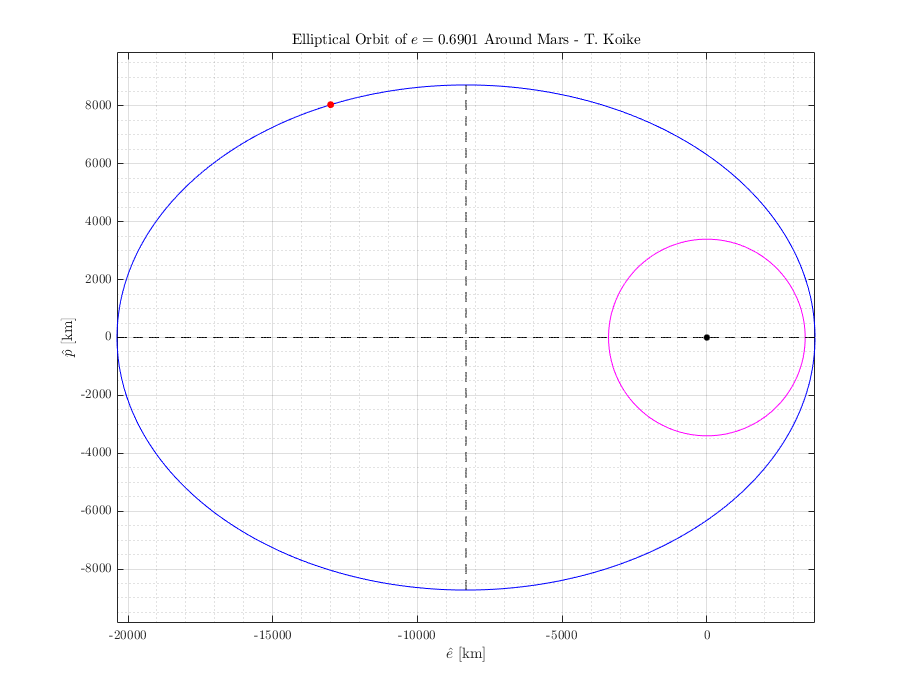

% (b)
% Ellipse 
theta = 0:0.01:2*pi;
R = p ./ (1 + e * cos(theta));
X = R .* cos(theta); Y = R .* sin(theta);

% Mars 
Xm = Rm * cos(theta); Ym = Rm * sin(theta);

% At time t1
X1 = r_1 * cosd(TA_1); Y1 = r_1 * sind(TA_1);

% Plot
fig = figure("Renderer","painters","Position",[10 10 900 700]);
    plot(X, Y, '-b')
    title('Elliptical Orbit of $e=0.6901$ Around Mars - T. Koike')
    hold on; grid on; grid minor; box on; axis equal;
    plot(X1, Y1, '.r', 'MarkerSize', 18)
    
    % Mars
    plot(Xm, Ym, '-m')
    plot(0, 0, '.k', 'MarkerSize', 15)
    % Axes
    nanikore = -ra:rp; korenani = -a*sqrt(1-e^2):a*sqrt(1-e^2);
    plot(nanikore, zeros(size(nanikore)), '--k')
    plot(-a*e*ones(size(korenani)), korenani, '--k')
    
    hold off
    xlabel('$\hat{e}$ [km]')
    ylabel('$\hat{p}$ [km]')
saveas(fig, fullfile(fdir, 'p1_orbit1.png'));

% (c)
EA_c = T2E_anomaly(e, TA_c, "deg");
dt_pc = sqrt(a^3 / mu) * (EA_c - e * sind(EA_c));
dt_pc_day = dt_pc / 60 / 60 / 24;
dt_c1 = dt_p1 - dt_pc;
dt_c1_day = dt_c1 / 60 / 60 / 24;

% (d)
r_new = r_1;
v_new = sqrt(mu / r_1);
v_1_vec = v_1 * [sind(FPA_1), cosd(FPA_1)];
v_new_vec = v_new * [0, 1];
dv_vec = v_new_vec - v_1_vec;
dv = norm(dv_vec);
syms alpha 
eqn = v_new / sind(180-alpha) == dv / sind(FPA_1);
alpha = solve(eqn, alpha)

$$alpha = \left(\begin{array}{c} 99.0138\\ 80.9862 \end{array}\right)$$

temp_ang = acosd(dot(v_new_vec, dv_vec)/ dv / v_new) + FPA_1

temp_ang =        99.014


% alpha = acosd(dot(v_new_vec, v_1_vec) / v_new / v_1);

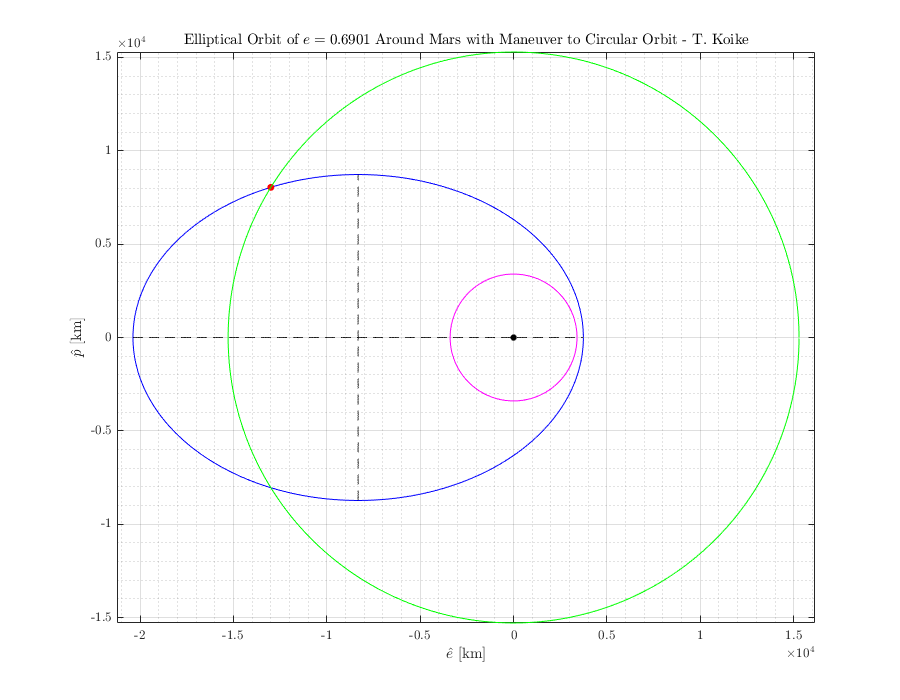

% (e)
% Ellipse 
theta = 0:0.01:2*pi;
R = p ./ (1 + e * cos(theta));
X = R .* cos(theta); Y = R .* sin(theta);

% Mars 
Xm = Rm * cos(theta); Ym = Rm * sin(theta);

% At time t1
X1 = r_1 * cosd(TA_1); Y1 = r_1 * sind(TA_1);

% New circular orbit
Xnew = r_1 * cos(theta); Ynew = r_1 * sin(theta);

% Plot
fig = figure("Renderer","painters","Position",[10 10 900 700]);
    plot(X, Y, '-b')
    title('Elliptical Orbit of $e=0.6901$ Around Mars with Maneuver to Circular Orbit - T. Koike')
    hold on; grid on; grid minor; box on; axis equal;
    plot(X1, Y1, '.r', 'MarkerSize', 18)
    
    % Mars
    plot(Xm, Ym, '-m')
    plot(0, 0, '.k', 'MarkerSize', 15)
    % Axes
    nanikore = -ra:rp; korenani = -a*sqrt(1-e^2):a*sqrt(1-e^2);
    plot(nanikore, zeros(size(nanikore)), '--k')
    plot(-a*e*ones(size(korenani)), korenani, '--k')
    
    % New orbit
    plot(Xnew, Ynew, '-g')
    
    hold off
    xlabel('$\hat{e}$ [km]')
    ylabel('$\hat{p}$ [km]')
saveas(fig, fullfile(fdir, 'p1_orbit2.png'));

% (f)
vvec1 = [-1.37, -0.4173];
vvec2 = [-0.8808, -1.4230];
Dv = vvec2 - vvec1;
Dv_orbital = Dv * [cosd(TA_1), -sind(TA_1); sind(TA_1), cosd(TA_1)];